# Group Assignment 04 

# Uncertainty in Electrical Components 

# Resistor Production

In production of 100 Ω resistors, the resistance of each resistors will be a random variable that is Gaussian distributed with a mean of 100 Ω, and a standard deviation of σ. 

The resistors are sorted in 5% and 10% resistors. Thus all resistors within 5% of 100 Ω are sorted in one package, and resistors between 5% and 10% are sorted in another package. Resistors deviating more than 10% are discarded.

resistor_val = 100;
mu = 100;

**Questions:**

1) Begin by assuming that σ = 5 Ω. How many percent on average of the produced resistors are in each package, and how many are discarded. Instead of a lookup table you can use the Matlab function normcdf(). Use the doc in Matlab to find out arguments in the function

std_dev = 5;
low_bound_five = 95;
low_bound_ten = 90;

% CDF we find the prob for getting x<95
prob_95 = normcdf(low_bound_five,mu,std_dev)

prob_95 = 0.1587


% CDF we find the prob for getting x<90
prob_90 = normcdf(low_bound_ten,mu,std_dev)

prob_90 = 0.0228


% Since the gaussian function is symmetrical we just subtract twice from
% the total prob meaning 95 >= x <= 105
prob_5 = (1 - 2 * prob_95) * 100

prob_5 = 68.2689


% 90 < 95 >= x >= 105 < 110 
prob_10 = 2 * (prob_95 - prob_90 ) * 100

prob_10 = 27.1810


% Probability of getting discard, meaning 90 < x > 110
prob_discard = 2 * (prob_90) * 100

prob_discard = 4.5500

2) Make a Matlab simulation that simulate 1000 resistors, and confirm the result obtained in question 1. Use Matlab’s randn() function.

n_resistors = 1000;
resistors = std_dev * randn(1, n_resistors) + mu;
Discarded_res = 0;
res_5 = 0;
res_10 = 0;

for i = 1 : n_resistors
    if (resistors(i) > 105 || resistors(i) < 90)
        Discarded_res = Discarded_res + 1;
    elseif (resistors(i) > 105 || resistors(i) < 95)
        res_10 = res_10 + 1;
    else
        res_5 = res_5 + 1;
    end
end

prob_5 = (res_5 / n_resistors) * 100

prob_5 = 68.1000

prob_10 = (res_10 / n_resistors) * 100

prob_10 = 13.6000

prob_discard = (Discarded_res / n_resistors) * 100

prob_discard = 18.3000

3) What should the standard deviation be if the packages of 5% resistors contains half of the resistors? Find the result with the function norminv().

std_dev_new = std_dev;
for n=1 : 10000
    if 95 < norminv(0.25, mu, std_dev_new)
        std_dev_new = std_dev_new + 0.001;
    end
end

std_dev_new

std_dev_new = 7.4140

4) Sample 1000 resistors, with the found standard deviation, plot the pdf and cdf with a hist() function in Matlab.

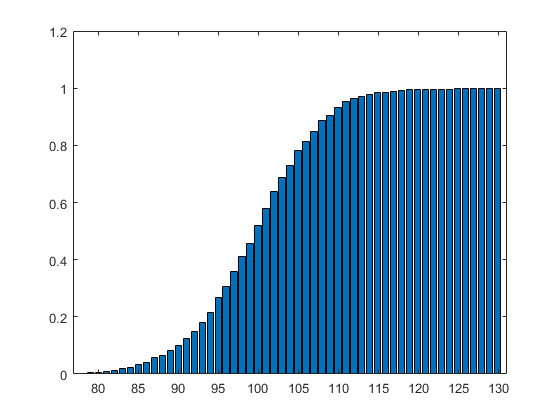

new_resistors = std_dev_new * randn(1,1000) + mu;
res_min = min(new_resistors);
res_max = max(new_resistors);

[nCounts, nCenters] = hist(new_resistors, res_max - res_min + 1);
pdf_of_all = nCounts/n_resistors;
cdf_of_all = cumsum(pdf_of_all);
bar(nCenters, cdf_of_all)

5) Find the mean and standard deviation of the 1000 samples, use the mean() and var() functions in Matlab.

std_dev_new = sqrt(var(new_resistors))

std_dev_new = 7.3606

mean_new = mean(new_resistors)

mean_new = 99.9260

6) Why are the found mean and standard deviation not exact?

Because the sample space/size is not big enough